Final adelantado soluciones en mlx. (Entrenamiento para final real)

# Ejercicio 1

clear all; clf;

## apartado a)

syms y [1 2] real

system(1, 1) = y(1)*(y(1)^2 + y(2)^2 - 1) - y(2);
system(2, 1) = y(1)+ y(2)*(y(1)^2+y(2)^2-1)

$$system = \left(\begin{array}{c} y_{1}\,\left({y_{1}}^{2}+{y_{2}}^{2}-1\right)-y_{2}\\ y_{1}+y_{2}\,\left({y_{1}}^{2}+{y_{2}}^{2}-1\right) \end{array}\right)$$

[y01, y02] = solve(system, [y(1), y(2)])

$$y01 = 0$$

$$y02 = 0$$

y0 = [y01, y02]

$$y0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

Analizar estabilidad

Linealizo el sistema, entorno al punto de equilibrio, lo aproximo al sistema lineal dado por el jacobiano evaluado en el punto de equilibrio (Teorema de Taylor).  

J = jacobian(system, y)

$$J = \left(\begin{array}{cc} 3\,{y_{1}}^{2}+{y_{2}}^{2}-1 & 2\,y_{1}\,y_{2}-1\\ 2\,y_{1}\,y_{2}+1 & {y_{1}}^{2}+3\,{y_{2}}^{2}-1 \end{array}\right)$$

%El sistema linealizado en torno al punto de equilibrio es igual al jacobiano
%evaluado en dicho punto de equilibrio por el vector de estado. 

%Evaluado en el punto de equilibrio es
J0 = subs(J, y, y0) %Que a su vez es la forma matricial del sistema linealizado. 

$$J0 = \left(\begin{array}{cc} -1 & -1\\ 1 & -1 \end{array}\right)$$

%linsis = subs(system, y, y0) + J0 * y'
eig(J0) %double(eig(J0))

$$ans = \left(\begin{array}{c} -1-\mathrm{i}\\ -1+\mathrm{i} \end{array}\right)$$

## apartado b)

%Calcular V mediante la forma general (función cuadrática). Usar la
%identidad para la ecuación de Lyapunov.
%Si el sistema linealizado presenta estabilidad de Lyapunov, se cumple la
%ecuación A'P + PA = -Q. Si hay exponencial -Q = -I
P = lyap(J0, eye(2));
%Y con esta P calculo V
V = y * P * y'

$$V = \frac{{y_{1}}^{2}}{2}+\frac{{y_{2}}^{2}}{2}$$

%Se ve de golpe que esta función es definida positiva en y != [0,0] y vale
%0 solo en el punto de equilibrio. Ahora calculo la derivada de Lie de esta
%función.
Vlie = gradient(V)' * system

$$Vlie = y_{2}\,\left(y_{1}+y_{2}\,\left({y_{1}}^{2}+{y_{2}}^{2}-1\right)\right)-y_{1}\,\left(y_{2}-y_{1}\,\left({y_{1}}^{2}+{y_{2}}^{2}-1\right)\right)$$

Vlie = simplify(Vlie)

$$Vlie = {y_{1}}^{4}+2\,{y_{1}}^{2}\,{y_{2}}^{2}-{y_{1}}^{2}+{y_{2}}^{4}-{y_{2}}^{2}$$

Esto tiene una forma de (y1^2 + y2^2)^2 - y1^2 - y2^2, es decir

Vlie = (y(1)^2 + y(2)^2)^2 - (y(1)^2 + y(2)^2)

$$Vlie = {\left({y_{1}}^{2}+{y_{2}}^{2}\right)}^{2}-{y_{1}}^{2}-{y_{2}}^{2}$$

Se necesita que y1 + y2 sea menor que 1 para que el sistema asintóticamente (Vlie < 0), luego el dominio de atracción puede considerarse y1^2 + y2^2 < 1. En caso de que esa suma de cuadrados sea mayor que 1, el sistema diverge (Vlie > 0). Y en la circunferencia de radio 1, la derivada es 0, por lo que el sistema debería presentar estabilidad local no asintótica. 

## apartado c)

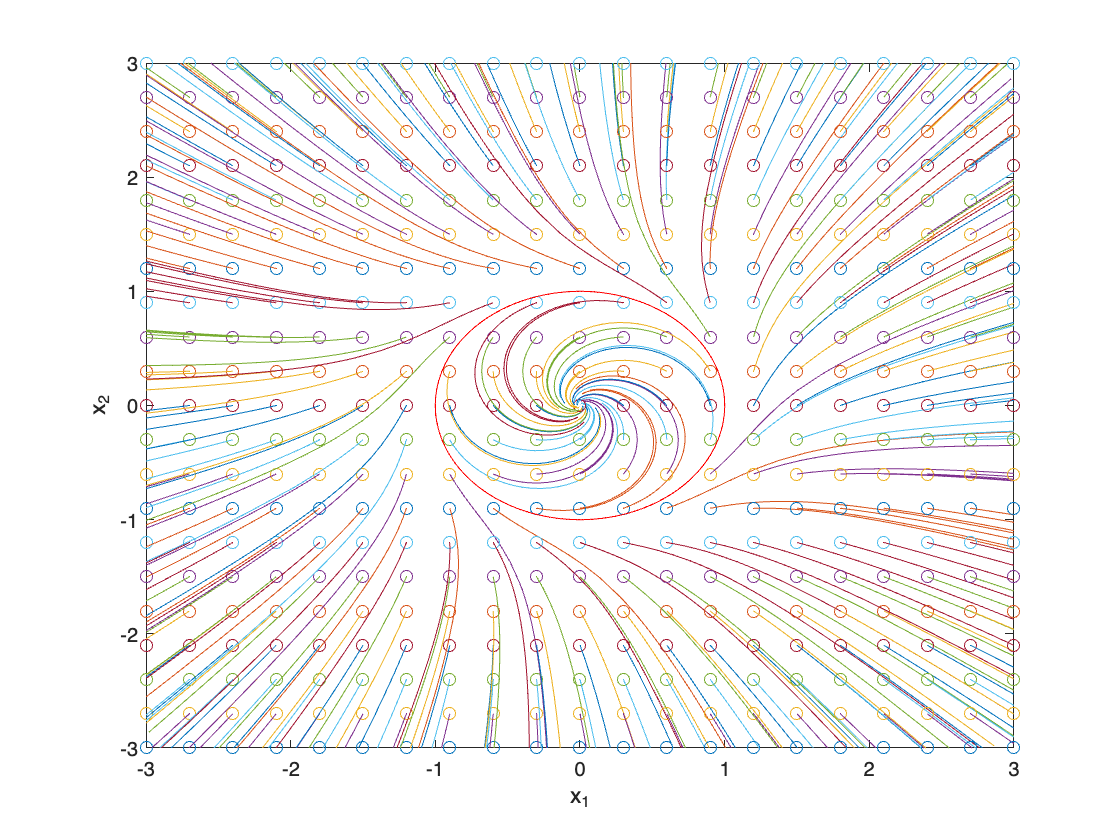

for i = -3:0.3:3
    for j = -3:0.3:3
       [t, x] = ode45(@sys, [0 3], [i; j]); %Recordar pasar siempre una condición inicial en columna
       plot(i, j, "o"); hold on;
       plot(x(:,1), x(:,2));
       xlim([-3 3]);
       ylim([-3 3]);
       xlabel("x_1")
       ylabel("x_2")
    end
end
%Se puede pintar la circunferencia de r = 1
th = 0:0.01:2*pi;
plot(cos(th), sin(th), "r", "MarkerSize", 5); hold off;

# Ejercicio 2

## Apartado a)

system2(1, 1) = -1 * system(1, 1)

$$system2 = y_{2}-y_{1}\,\left({y_{1}}^{2}+{y_{2}}^{2}-1\right)$$

system2(2, 1) = -1 * system(2, 1)

$$system2 = \left(\begin{array}{c} y_{2}-y_{1}\,\left({y_{1}}^{2}+{y_{2}}^{2}-1\right)\\ -y_{1}-y_{2}\,\left({y_{1}}^{2}+{y_{2}}^{2}-1\right) \end{array}\right)$$

%Buscamos puntos de estabilidad
[y10, y20] = solve(system2, [y(1), y(2)])

$$y10 = 0$$

$$y20 = 0$$

%Si ahora miramos la estabilidad del punto de equilibrio
%Linealizar sistema 2

J20 = subs(jacobian(system2, y), y, [y10, y20])

$$J20 = \left(\begin{array}{cc} 1 & 1\\ -1 & 1 \end{array}\right)$$

%Esta es la matriz del sistema linealizado, que tendrá por autovalores
eig(J20)

$$ans = \left(\begin{array}{c} 1-\mathrm{i}\\ 1+\mathrm{i} \end{array}\right)$$

La parte real es positiva, lo que apunta a que sea un punto de equilibrio inestable. 

%Recuperando la función de Lyapunov calculada previamente
V

$$V = \frac{{y_{1}}^{2}}{2}+\frac{{y_{2}}^{2}}{2}$$

%Escribimos la derivada de Lie
Vlie2 = simplify(gradient(V)'* system2)

$$Vlie2 = -{y_{1}}^{4}-2\,{y_{1}}^{2}\,{y_{2}}^{2}+{y_{1}}^{2}-{y_{2}}^{4}+{y_{2}}^{2}$$

Que es naturalmente opuesta a la derivada de Lie del otro ejercicio. Esta vez, para que sea negativa, y1^2 + y2^2 debe ser mayor que uno, y será positiva para los valores que cumplan y1^2 + y^2 < 1. De modo que para r > 1, el sistema trata de converger al punto de equilibrio. Pero para r < 1, el sistema diverge. El resultado será una convergencia global a la circunferencia r = 1, que será un ciclo límite. uwu. 

## Apartado b)

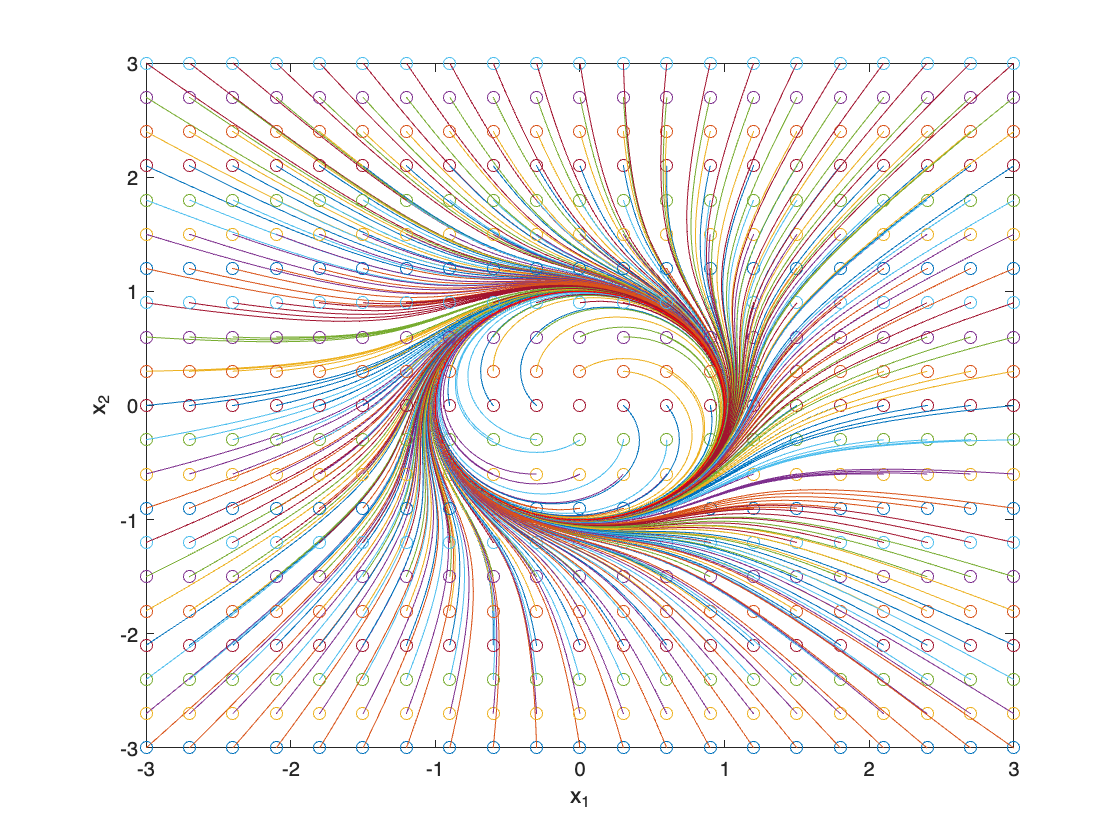

%El sistema es igual pero en negativo, así que lo que hago es integrar el original pero en un tiempo negativo
for i = -3:0.3:3
    for j = -3:0.3:3
       [t, x] = ode45(@sys, [0 -3], [i; j]); %Recordar pasar siempre una condición inicial en columna
       plot(i, j, "o"); hold on;
       plot(x(:,1), x(:,2));
       xlim([-3 3]);
       ylim([-3 3]);
       xlabel("x_1")
       ylabel("x_2")
    end
end
%Se puede pintar la circunferencia de r = 1
th = 0:0.01:2*pi;
plot(cos(th), sin(th), "r", "MarkerSize", 5); hold off;

Y se aprecia todo lo discutido anteriormente. <3. 

%% Sección Funciones

function xdot = sys(t, y)
xdot(1,1) = y(1) * (y(1)^2 + y(2)^2 - 1) - y(2);
xdot(2,1) = y(1) + y(2)*(y(1)^2 + y(2)^2 - 1);
end 